close all; clear all; clc;

N=512; % signal length
M=120; % select the number of DCT coefficients

% Load the test signal
load mit200
x=ecgsig(1:N,1);

% DCT transform of signal (FROM MOTE)
y = [-55.0  -14.0  11.0  27.0  1.0  -54.0  15.0  38.0  -10.0  -24.0  18.0  34.0  -1.0  -4.0  -12.0  27.0  4.0  7.0  -25.0  23.0  4.0  16.0  -19.0  12.0  4.0  20.0  -10.0  0.0  0.0  14.0  5.0  -4.0  0.0  1.0  17.0  -2.0  2.0  -11.0  15.0  0.0  9.0  -15.0  10.0  0.0  16.0  -13.0  0.0  -2.0  13.0  -2.0  -3.0  -4.0  6.0  5.0  -1.0  -3.0  -2.0  5.0  0.0  1.0  -7.0  3.0  0.0  5.0  -8.0  0.0  -3.0  5.0  -5.0  -1.0  -5.0  5.0  -2.0  0.0  -6.0  1.0  -2.0  0.0  -4.0  0.0  -1.0  0.0  -1.0  -1.0  -1.0  -3.0  0.0  -2.0  0.0  -3.0  1.0  -2.0  2.0  -4.0  1.0  -2.0  1.0  -3.0  1.0  -1.0  2.0  -1.0  1.0  -1.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  1.0  0.0  0.0  0.0  1.0  -1.0  1.0  0.0  2.0  0.0  0.0  0.0  2.0  0.0  0.0  0.0  2.0  1.0  2.0  1.0  1.0  0.0  1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  1.0  0.0  1.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  -1.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  -1.0  0.0  -1.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  -1.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0  0.0  0.0  0.0  0.0  0.0  1.0  0.0  0.0];

% apply scaling
y(1)=1/sqrt(N)*y(1);
y(2:end)=sqrt(2/N)*y(2:end);

%% Select first M coefficients
y(M+1:end)=0;

%% reconstructed signal
x_rec=idct(y);

% Mean square
mse(x,x_rec);

plot(x);
hold on;
plot((x_rec), 'r.');
fprintf('Mean square: %f\n', mse(x,x_rec))

Mean square: 0.119003


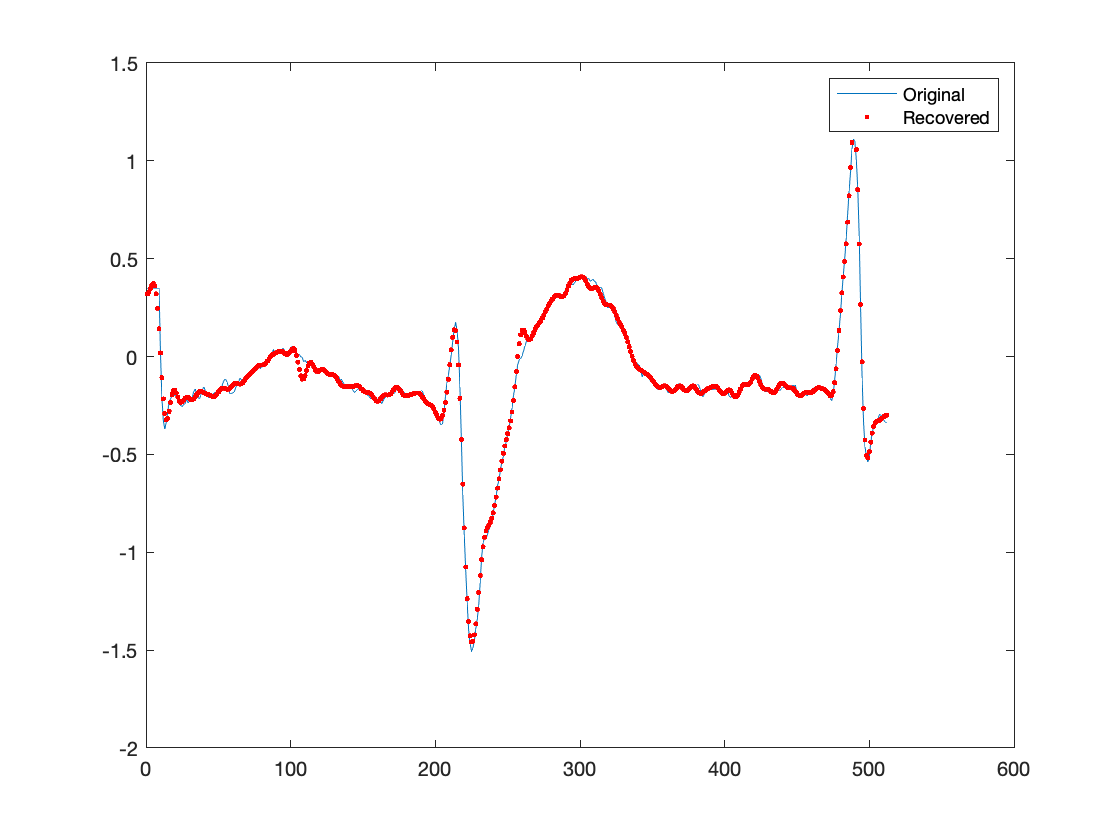

legend('Original', 'Recovered')